% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\Box.STL");

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 20)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [12×3 double]
       numOfElements: 12
              points: [8×3 int64]
      sliceThickness: 20
           slicePath: [0×3 double]


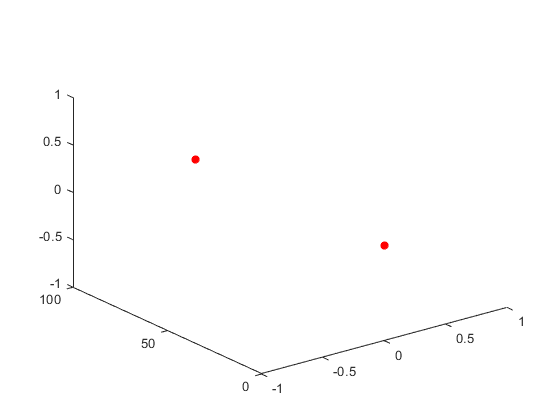


% Generate
figure(3)
uSGO1.generateSlices()

op = uSGO1.getSlicePath()

% Show
figure(4)
plot3(op(:,1), op(:,2), op(:,3),'-r*','LineWidth',2);
view(3);
hold on